% Load data
load("data_2.mat");

% Filter the raw EEG
delta_eeg = filter(delta_filter(), signal);
theta_eeg = filter(theta_filter(), signal);
alpha_eeg = filter(alpha_filter(), signal);
beta_eeg = filter(beta_filter(), signal);

% Calculate RMS envelopes
% fs = 200; % Sampling rate
window_size = 30 * Fs; % 30-second window
[delta_uenv, delta_lenv] = envelope(delta_eeg, window_size, 'rms');
[theta_uenv, theta_lenv] = envelope(theta_eeg, window_size, 'rms');
[alpha_uenv, alpha_lenv] = envelope(alpha_eeg, window_size, 'rms');
[beta_uenv, beta_lenv] = envelope(beta_eeg, window_size, 'rms');
[raw_uenv, raw_lenv] = envelope(signal, window_size, 'rms');

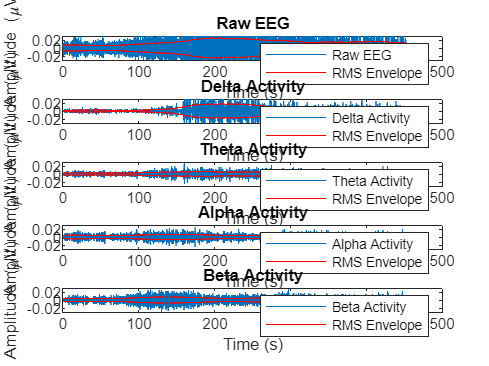

% Plot signals
t = (0:length(signal)-1)/Fs;
figure;
subplot(5,1,1);
plot(t, signal);
title('Raw EEG');
xlabel('Time (s)');
ylabel('Amplitude (\muV)');
set(gca, 'ylim', [-0.03 0.03]);
hold on;
plot(t, raw_uenv, 'r');
plot(t, raw_lenv, 'r');
legend('Raw EEG', 'RMS Envelope');

subplot(5,1,2);
plot(t, delta_eeg);
title('Delta Activity');
xlabel('Time (s)');
ylabel('Amplitude (\muV)');
set(gca, 'ylim', [-0.03 0.03]);
hold on;
plot(t, delta_uenv, 'r');
plot(t, delta_lenv, 'r');
legend('Delta Activity', 'RMS Envelope');

subplot(5,1,3);
plot(t, theta_eeg);
title('Theta Activity');
xlabel('Time (s)');
ylabel('Amplitude (\muV)');
set(gca, 'ylim', [-0.03 0.03]);
hold on;
plot(t, theta_uenv, 'r');
plot(t, theta_lenv, 'r');
legend('Theta Activity', 'RMS Envelope');

subplot(5,1,4);
plot(t, alpha_eeg);
title('Alpha Activity');
xlabel('Time (s)');
ylabel('Amplitude (\muV)');
set(gca, 'ylim', [-0.03 0.03]);
hold on;
plot(t, alpha_uenv, 'r');
plot(t, alpha_lenv, 'r');
legend('Alpha Activity', 'RMS Envelope');

subplot(5,1,5);
plot(t, beta_eeg);
title('Beta Activity');
xlabel('Time (s)');
ylabel('Amplitude (\muV)');
set(gca, 'ylim', [-0.03 0.03]);
hold on;
plot(t, beta_uenv, 'r');
plot(t, beta_lenv, 'r');
legend('Beta Activity', 'RMS Envelope');

% Calculate spectrogram
window_size = 30 * Fs;
overlap_size = 29 * Fs;
freq_range = 0.1:0.1:32;
[S,F,T,P] = spectrogram(signal, window_size, overlap_size, freq_range, Fs);

% frequency ranges
delta_idx = find(F>=1 & F<4);
theta_idx = find(F>=4 & F<8);
alpha_idx = find(F>=8 & F<12);
beta_idx = find(F>=12 & F<25);

% Calculate relative powers
total_power = sum(P, 1); % total power across all frequencies

delta_rel_power = sum(P(delta_idx,:), 1) ./ total_power;
theta_rel_power = sum(P(theta_idx,:), 1) ./ total_power;
alpha_rel_power = sum(P(alpha_idx,:), 1) ./ total_power;
beta_rel_power = sum(P(beta_idx,:), 1) ./ total_power;

% Normalize the power spectral density estimates
norm_P = P./sum(P, 1);

% Calculate the number of frequency bins
Nf = size(P, 1);

% Calculate the spectral entropy for each time point
SE = -sum(norm_P.*log2(norm_P),1)./log2(Nf);

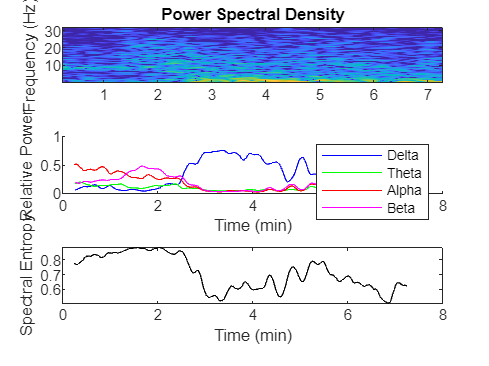

% Plot results
figure;
subplot(3,1,1);
imagesc(T/60,F,log10(P),[-7 -3]);
axis xy;
ylabel('Frequency (Hz)');
title('Power Spectral Density');

subplot(3,1,2);
hold on;
plot(T/60, delta_rel_power, 'b');
plot(T/60, theta_rel_power, 'g');
plot(T/60, alpha_rel_power, 'r');
plot(T/60, beta_rel_power, 'm');
xlabel('Time (min)');
ylabel('Relative Power');
ylim([0 1]);
legend('Delta', 'Theta', 'Alpha', 'Beta');

subplot(3,1,3);
plot(T/60, SE, 'k');
xlabel('Time (min)');
ylabel('Spectral Entropy');